# Diskret Stokatisk

## Eksempel 1

clearvars
% E[X] = sum af x*fx
x = [-3, 0, 2, 4, 7, 10, 12];
k = 1/7;
fx = k;
Ex = sum(x.*fx)

Ex = 4.5714

% Varians = E[X^2] - E[X]^2
Ex2 = sum((x.^2).*fx)

Ex2 = 46

var = Ex2-Ex^2

var = 25.1020

## Eksempel 2

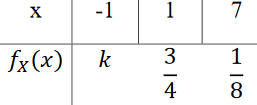

clearvars
k = 1/8;
% E[X]= sum af x*fx
x = [-1, 1, 7];
% Definer fx som et array, og så gang dem sammen. Dette er klart nemmeste til den her..
fx = [k, 3/4, 1/8]

fx =     0.1250    0.7500    0.1250


Ex = sum(x.*fx)

Ex = 1.5000

% Varians = E[X^2] - E[X]^2
% Standard Afvigelse = kvadratroden af variansen
Ex2 = sum((x.^2).*fx);
var = Ex2-Ex^2;
std = sqrt(var)

std = 2.1794

## Eksempel 3

Bestem middelværdi og variansen for X

clearvars
syms x
x_val = [-4, -2, 0, 2, 4];
fx = piecewise(x==-4,3/12, x==-2,3/12, x==0,3/12, x==2,2/12, x==4,1/12,0)

$$fx = \left\{ \begin{array}{cl} \frac{1}{4} & \text{ if }x\in \left\{-4,-2,0\right\}\\ \frac{1}{6} & \text{ if }x=2\\ \frac{1}{12} & \text{ if }x=4\\ 0 & \mathrm{otherwise} \end{array}\right.$$

% Definer fx værdierne i et array - nemmeste løsning
fx_a = [3/12, 3/12, 3/12, 2/12, 1/12];
% E[X]= sum af x*fx
Ex = sum(x_val.*fx_a)

Ex = -0.8333

% Varians = E[X^2] - E[X]^2
Ex2 = sum((x_val.^2).*fx_a)

Ex2 = 7

var = Ex2-Ex^2

var = 6.3056

## Eksempel 4

Find middelværdi og varians

clearvars
% Givet følgende:
x = [0, 1, 2, 3, 4, 5];
fx = [0.2, 0.15, 0.15, 0.15, 0.25, 0.10];

% E[X] = sum af x*fx
Ex = sum(x.*fx)

Ex = 2.4000


% Varians = E[X^2] - E[X]^2
Ex2 = sum((x.^2).*fx)

Ex2 = 8.6000

var = Ex2 - Ex^2

var = 2.8400

# Kontinuert Stokastisk

## Eksempel 1

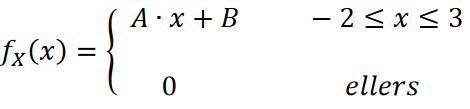

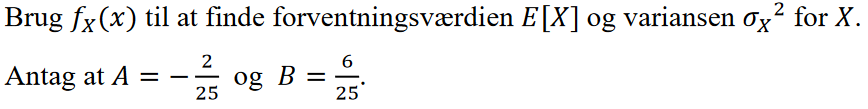

% Antagelser
A = -(2/25); B = 6/25;
% Det er kun nødvendigt at undersøge intervallet -2 til 3, da alle andre værdier er 0
syms x
fx = A*x+B;
% E[X] = integralet af x*fx fra -2 til 3
Ex = int(x*fx, x, -2, 3)

$$Ex = -\frac{1}{3}$$


% Varians = E[X^2] - E[X]^2
Ex2 = int((x^2)*fx, x, -2, 3)

$$Ex2 = \frac{3}{2}$$

var = double(Ex2-Ex^2) % Bruger double for at få outputtet i decimal i stedet for fraction

var = 1.3889

## Eksempel 2

 

clearvars
syms x
% Antagelser
a = 1/4;
% Givet er følgende pdf:
fx = piecewise(x<0, 0, 0<=x<=2, 2*a*x, x>2, 0)

$$fx = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ \frac{x}{2} & \text{ if }x\in \left[0,2\right]\\ 0 & \text{ if }2<x \end{array}\right.$$

% E[X] = integralet af x*fx fra 0 til 2
Ex = double( int(x*fx, x, 0, 2) )% Integralet af x*fx i forhold til x, fra 0 til 2

Ex = 1.3333


% Varians = E[X^2] - E[X]^2
Ex2 = int((x^2)*fx, x, 0, 2)

$$Ex2 = 2$$

var = double(Ex2-Ex^2) % Double for at få output som decimal

var = 0.2222

## Eksempel 3

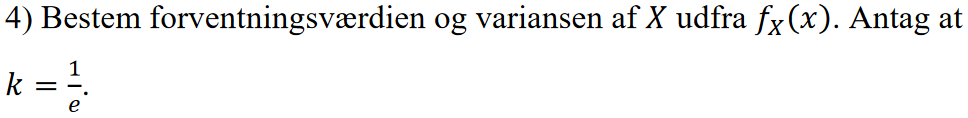

clearvars
% Vi er interesseret i intervallet -uendelig til 1
k = 1/exp(1);
syms x
fx = k*exp(x);

% E[X]= integralet af x*fx fra -uendelig til 1
Ex = double( int(x*fx, x, -inf, 1) )

Ex = 0


% Varians = E[X^2] - E[X]^2
Ex2 = int((x^2)*fx, x, -inf, 1);
var = double( Ex2-Ex^2 )

var = 1.0000

## Eksempel 4

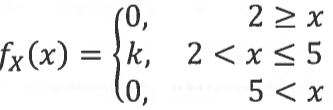

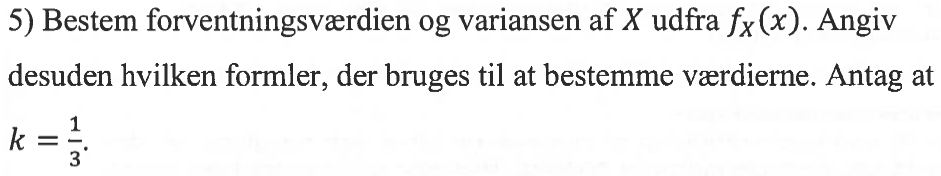

clearvars
% Vi er kun interesseret i intervallet 2 til 5, da alle andre værdier er 0
k = 1/3;
syms x
fx = k;
% E[X]= integralet af x*fx fra 2 til 5
Ex = double ( int(x*fx, x, 2, 5) )

Ex = 3.5000


% Varians = E[X^2] - E[X]^2
Ex2 = int( (x^2)*fx, x, 2, 5 );
var = double( Ex2-Ex^2 )

var = 0.7500